## Model 1 Probit - Gibbs

### Load data to use:

Apply the program to the dataset on mortgage applications (loanapp.csv).

% Specify the file path
filePath = 'loanapp.csv';

% Read the CSV file into a table
loanTable = readtable(filePath);

% remove the missing value from the dataset
loanTable = rmmissing(loanTable);

% Get the size of the dataset
datasetsize = size(loanTable);

% Display the size of the dataset
disp(['Number of Rows: ', num2str(datasetsize(1))]);      % 1777

Number of Rows: 1777


disp(['Number of Columns: ', num2str(datasetsize(2))]);   % 59

Number of Columns: 59


### Generate the y and X for the Probit model:

As this is a Probit model, we assume


$$y_i = \beta_0 + \beta_1 x_{1i} + \beta_2 x_{2i} + \cdots + \beta_p x_{pi} + u_i , \quad i = 1, \ldots, n$$


with $u_i \overset{iid}{\sim} \mathcal{N}(0, \sigma^2)$. In matrix form, this can be written as$y = X\beta + u$ where $y = (y_1, \ldots, y_n)$, $u = (u_1, \ldots, u_n)$ and 


$$X=\left\lbrack \begin{array}{ccccc}
1 & x_{11}  & x_{21}  & \cdots  & x_{\textrm{p1}} \\
1 & x_{12}  & x_{22}  & \cdots  & x_{\textrm{p2}} \\
\vdots  & \vdots  & \vdots  & \ddots  & \vdots \\
1 & x_{1n}  & x_{2n}  & \cdots  & x_{\textrm{pn}} 
\end{array}\right\rbrack$$


Then, we generate the dependent variable and independent variables X based on above form.

For the data, we will use:

    dependend varibale y: whether an individual was approved for a mortgage loan (approve)

    independent variable: 

- housing expenditures as percentage of total income (hrat)

- other obligations as percentage of total income (obrat)

- loan amount as percentage of house price (loanprc)

- unemployment rate in industry of occupation (unem)

- number of dependents (dep)

- dummy for high school education (sch)

- dummy for presence of cosigner (cosign)

- dummy for previous bankrupcy (pubrec)

- marriage status (married)

- dummy for white race (white)

- and dummy for sex (male)

We will have p = 11 and n equal to the the length of y vector.

% generate y and X

% generate outcome variable y
y_Data = loanTable(:, 'approve');
y = [table2array(y_Data)];

p = 11;
n = datasetsize(1);

X_Col = {'hrat', 'obrat', 'loanprc', 'unem', 'dep', 'sch', 'cosign', 'pubrec', 'married', 'white', 'male'}; 
% Extract the selected columns from the table
X_Data = loanTable(:, X_Col);

% generate X
X = [ones(n, 1), table2array(X_Data)];       % n * (p+1)

### Set prior hyperparameters:

We will use the following noninformative prior values:


$$\underline{B} = 1000 \cdot I_{p+1}$$
          
$$\underline{\alpha} = 0.02$$
            

             
$$\underline{\beta} = 0_{p+1}$$
                    
$$\underline{\delta} = 0.02$$
				

where $I_{p+1}$ is an identity matrix of size (p + 1) × (p + 1) and $0_{p+1}$ is a vector of zeros of dimension p + 1. 

% other noninformative prior values
I = eye(p + 1);                     % identity matrix of size (p+1)*(p+1)
zeroVector = zeros(p + 1, 1);       % a vector of zeros of dimension p + 1

B_underbar = 1000 * I;              % B = 1000·Ip+1; (p+1)*(p+1)
beta_underbar = zeroVector;         % β = 0p+1; (p+1)*1
alpha_underbar = 0.02;              % α = 0.02    
delta_underbar = 0.02;              % δ = 0.02

B_underbari = inv(B_underbar);

### Set algorithm values

1. Specify the burn-in and main iteration periods

We use a burn-in period of 5,000 iterations and keep 10,000 final iterations to estimate posterior means (for a total of 15,000 iterations). 

% iterations to estimate posterior means
burn_in_iter = 5000;                  % burn-in period of 5,000 iterations 
final_iter = 10000; 
nsim = burn_in_iter + final_iter + 1; % 15,000 final iterations

keep = (burn_in_iter + 2) : nsim;     % keep value for the final_iter

2. Specify initial values

In our modal, we use a latent variable representation to formalize the model. Let $y^*$ be a latent unobserved variable that is related to the observed outcome y, where 


$$y_i^* = \beta_0 + \beta_1 x_{1i} + \beta_2 x_{2i} + \cdots + \beta_p x_{pi} + u_i = x^\top \beta + u_i, \quad i = 1, \ldots, n$$


Here, $\beta = (\beta_0, \beta_1, \ldots, \beta_p)$ is a p + 1 vector of coefficients and we assume that with $u_i \overset{iid}{\sim} \mathcal{N}(0, \sigma^2)$ independently across units i. This latent variable represents the difference in utility between options$y_i = 1$and$y_i = 0$, also known as the marginal utility for individual i. 

To relate the latent variable $y_i ^ *$ to the observable action $y_i$, we assume the individual chooses $y_i = 1$whenever the utility of doing so is positive ($y_i ^* > 0 $) and chooses$y_i = 0$ otherwise. 

We also impose $\sigma^2$ = 1.

Then, we can initialize the value for coefficient vecor $\beta$ and $y^*$, and $u_i$.

% Initialize variables
beta_gibbs = zeros(nsim, p + 1);
y_star_gibbs = zeros(nsim, n);
beta_gibbs(1, :) = beta_underbar;

sigma2 = 1;                             % impose σ^2 = 1
u = normrnd(0, sqrt(sigma2), [n, 1]);   % u ~ N(0, σ^2) with n*1

3. Gibbs sampling:

The posterior, $p(y^*,\beta|y) \propto p(y|y^*,\beta) p(y^*,\beta)$.

We would write the likelihood of $y$ in terms of $\beta$ and $y^*$, which is $p(y|\beta, y^*)$, and it should follow the probit model. 

Then for the prior, we have $p(y^*,\beta) = p(y^*|\beta)p(\beta)$ with


$$p(y^*|\beta) = \sum_{i=1}^{n} \text{N}(y_i^*|x_i^{\top}, 1)$$



$$p(\beta) = \text{N}_{p+1}(\underline{\beta}, \underline{B})$$


For the latent variable$y^*$, we define two sets $C_0$ and $C_1$ for the observations with outcome 0 or 1, i.e., $C_0 = \{ i: y_i = 0\}$and $C_1 = \{ i: y_i = 1\}$. We can then obtain the conditional posteriors as

For all $i \in C_0$, $y_i^* |\beta,y \sim \text{TN}_{(-\infty,0]}(x_i^\top\beta,1)$

Fot all $i \in C_1$, $y_i^* |\beta,y \sim \text{TN}_{(0,\infty)}(x_i^\top\beta,1)$

For prior $\beta$:


$$\beta|y^*, y \sim \text{N}_{p+1}(\bar{\beta}, \bar{B})

$$


We need to initialize the $y^*$ with the trauncated distribution.

% To compute the y_star
% set y_star(0) by y whether > 0, and it is a n d
prob = sum(y == 1) / n;
mean_value = norminv(prob, 0, 1);

y_star_1 = zeros(n, 1);   % initial y_star 

% truncated distribution
for t = 1 : n
    if y(t) == 1
        y_star_1(t) = mvnrnd(mean_value, 1);
        while y_star_1(t) <= 0
            y_star_1(t) = mvnrnd(mean_value, 1);
        end
    else
        y_star_1(t) = mvnrnd(mean_value, 1);
        while y_star_1(t) > 0
            y_star_1(t) = mvnrnd(mean_value, 1);
        end
    end
end

% combination
y_star_gibbs(1, :) = y_star_1;


Then we generalized our main simulation loop to get the posterior.

In each iteration, the value of $\beta $ will be updated by $y^*$ and the value of $y^*$will be updated with the calculated $\beta$. Then we implment for 15000 iterations.

% main simulation loop to get the posterior

for s = 2 : nsim
    % get beta(2) condition on y_star(1)
    B_bar = inv(X' * X ./ sigma2 + B_underbari);
    Beta_bar = B_bar * (X' * y_star_gibbs(s - 1, :)' ./ sigma2 + B_underbari * beta_underbar);

    beta_gibbs(s, :) = mvnrnd(Beta_bar, B_bar);

    % get y_star(2) condition on beta(2)
    % truncated distribution
    for i = 1 : n
        y_star_is = mvnrnd(X(i, :) * beta_gibbs(s, :)', 1);
        % positive for set C1
        if y(i) == 1
            while y_star_is <= 0
                y_star_is = mvnrnd(X(i, :) * beta_gibbs(s, :)', 1);
            end
        % negative for set C0
        else
            while y_star_is > 0
                y_star_is = mvnrnd(X(i, :) * beta_gibbs(s, :)', 1);
            end
        end
        % update y_star
        y_star_gibbs(s, i) = y_star_is;
    end
end

### Summary of posteriors:

We should drop the value for the burn-in iterations and only keep the value for the last 10000 iterations.

% Remove the Burn-in iterations and only keeop the final iteration betas
% Store samples after burn-in iterations
beta_final = beta_gibbs(keep, :);
y_star_final = y_star_gibbs(keep, :);

% estimate
beta_means = mean(beta_final)';
beta_medians = median(beta_final)';
beta_sds = std(beta_final)';
y_star_means = mean(y_star_final)';
y_star_medians = median(y_star_final)';
y_star_sds = std(y_star_final)';

%print
beta = [beta_means, beta_medians]';
row = {'mean', 'median'};
array2table(beta, 'RowNames', row)

ans = 2×12 table
              beta1       beta2        beta3       beta4        beta5        beta6        beta7        beta8       beta9      beta10     beta11      beta12  
              ______    _________    _________    ________    _________    _________    __________    ________    ________    _______    _______    _________

    mean      2.3345    0.0088207    -0.029878    -0.95529    -0.041613    -0.019799    0.00064842    0.073814    -0.95816    0.28431    0.64527    -0.023494
    median    2.3345    0.0087764     -0.02987    -0.95296     -0.

 Let's also get the trace plots, density plots and autocorrelation plots.

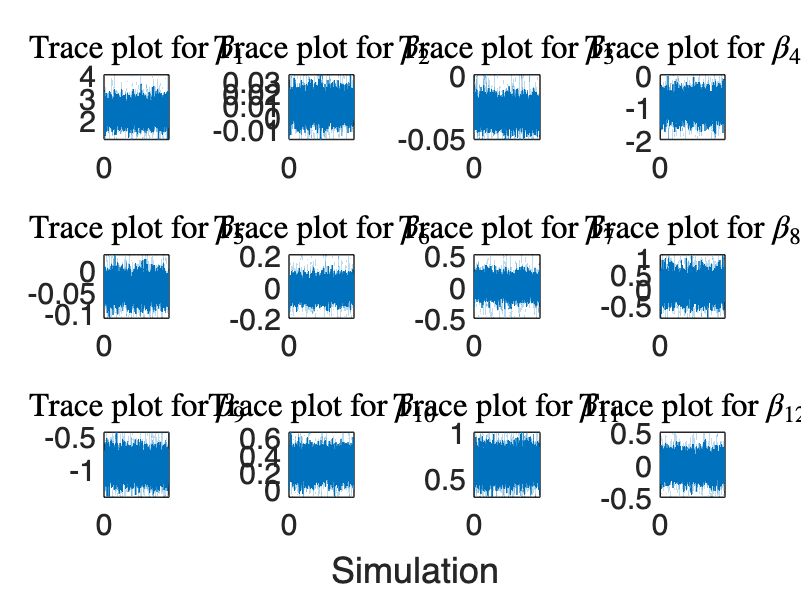

% Trace plots
figure
t = tiledlayout(3, 4);
for j = 1:p+1
    nexttile
    plot(beta_final(:, j))
    hold on
    title("Trace plot for $\beta_{" + j + "}$")
    hold off
end
xlabel(t, "Simulation")

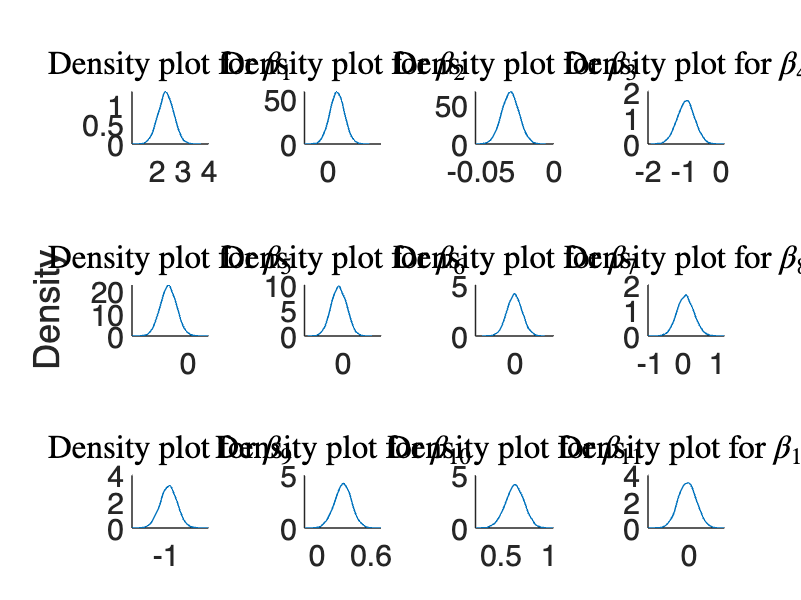

% Density plots
figure
t = tiledlayout(3, 4);
for j = 1:p+1
    nexttile
    hold on
    ksdensity(beta_final(:, j))
    hold off
    title("Density plot for $\beta_{" + j + "}$")
end
ylabel(t, "Density")

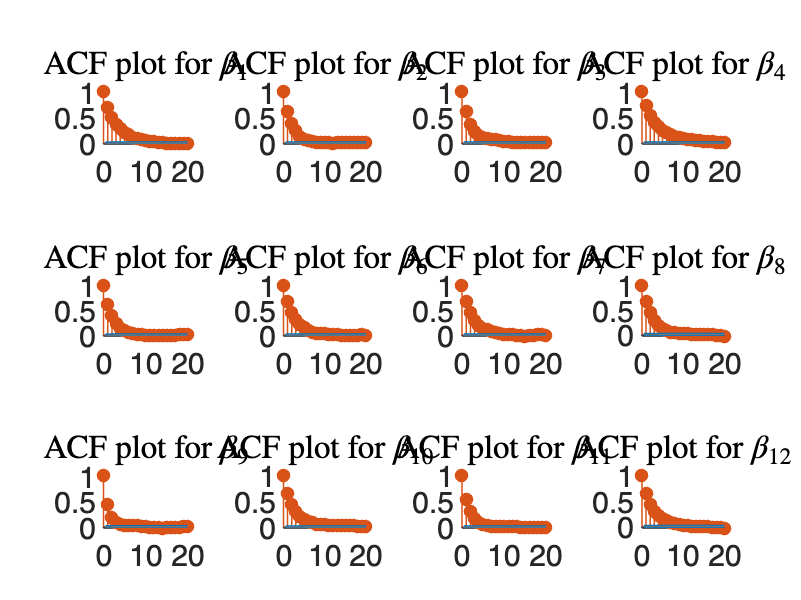

% Autocorrelation plots
figure
tiledlayout(3, 4);
for j = 1:p+1
    nexttile
    hold on
    autocorr(beta_final(:, j))
    hold off
    title("ACF plot for $\beta_{" + j + "}$")
end

**Trace plot:** Accoding to the trace plot, each $\beta_i$ is centered as some mean value the variations is also small. We think it converges to the stationary distribution.

**Density curve: **The density curve provides a smoothed representation of the distribution of sampled values. It helps visualize the shape of the distribution from which the samples are drawn. In our case, we used the Truncated normal distribution as the conditional posterior of getting the likelihood function of y. Generally, it seems our Gibbs sampling provieds a density curve that closely represnets the true posterior distribution. 

**ACF: **The ACF plot for a Gibbs sampling chain shows how quickly the correlations between samples decrease as the lag increases. Based on the ACF plots, it seems we have autocorrelation among sampled values and the autocolaation decreaes very fast as lag increases. This indicates that samples become quickly independent of each other, and the chain is mixing well and works efficiently.

### Marginal Effects:

To explain the effect of each $\beta_i$ on the outcome $y$ in the Probit model, we need to take the marginal effects on our $\beta_i$.

% Assuming beta_draws is your matrix of posterior draws
% Each row in beta_draws is a draw from the posterior distribution
% Columns represent different coefficients

% Assuming X is your data matrix (excluding the dependent variable)
% Initialize matrix to store predicted probabilities
predicted_probs = zeros(size(X,1), size(beta_final,1));

for i = 1:size(beta_final,1)
    predicted_probs(:,i) = normcdf(X * beta_final(i,:)');
end

% Initialize matrix to store marginal effects
marginal_effects = zeros(size(X,2), size(beta_final,1));

for i = 1:size(beta_final,1)
    % Calculate the linear predictor for this draw
    z = X * beta_final(i,:)';
    % Calculate the PDF of the normal distribution at these values
    pdf_values = normpdf(z);
    % Calculate marginal effects for each variable
    for j = 1:size(X,2)
        marginal_effects(j,i) = mean(pdf_values .* X(:,j) * beta_final(i,j));
    end
end

% Average the marginal effects across all draws
average_marginal_effects = mean(marginal_effects,2);
disp(average_marginal_effects)

    0.4033
    0.0391
   -0.1801
   -0.1356
   -0.0296
   -0.0030
   -0.0002
    0.0001
   -0.0241
    0.0287
    0.0787
   -0.0035



**Explanation of each marginal effect βi on the probit model:**

Marginal effect of $\beta_1$ = 0.4033: This value indicates the baseline probability of being approved for a mortgage loan when all other independent variables in the model are set to zero. A marginal effect of 0.4033 for the constant means that, before considering the specific effects of any individual variables (like income, loan amount as a percentage of house price, or employment status), there's an inherent probability of 40.33% that an applicant would be approved for a mortgage loan, holding all other factors constant. The significance of this baseline approval probability highlights the model's starting point for predictions. It represents the likelihood of loan approval based on the average or default conditions within the data set before any specific characteristics of an applicant are taken into account. This foundational probability is crucial for understanding how each additional variable adjusts the likelihood of approval up or down from this initial benchmark.

Marginal effect of $\beta_2$ = 0.0391: If the marginal effect of the independent variable—housing expenditures as a percentage of total income—on the probability of being approved for a mortgage loan in a probit model is 0.0391, this means that for every one percentage point increase in housing expenditures as a percentage of total income, the probability of an individual being approved for a mortgage loan increases by 3.91 percentage points, holding all other factors constant. This interpretation directly applies to the change in probability, making it straightforward: as individuals allocate a larger portion of their total income to housing expenditures, they are more likely to be approved for a mortgage, by a margin of approximately 3.91 percentage points for each one percentage point increase in that ratio.

Marginal effect of $\beta_3$ = -0.1801: A marginal effect of -0.1801 means that for every one percentage point increase in this other obligations as percentage of total income variable, the probability of an individual being approved for a mortgage loan decreases by 18.01 percentage points, holding all other factors constant.

Marginal effect of $\beta_4$ = -0.1356: In the same probit model, if there's an independent variable representing the loan amount as a percentage of the house price, and its marginal effect on the probability of being approved for a mortgage loan is -0.1356, this means that for every one percentage point increase in the loan amount relative to the house price, the probability of an individual being approved for a mortgage loan decreases by 13.56 percentage points, holding all other factors constant.

Marginal effect of $\beta_5$ = -0.0296: Beta5 is an independent variable in the model denoting the unemployment rate within the applicant's field of work, and its marginal effect on securing a mortgage loan approval is -0.0296, this suggests that with each one percentage point uptick in the industry's unemployment rate, the likelihood of mortgage approval falls by 2.96 percentage points, assuming all other variables remain unchanged.

Marginal effect of $\beta_6$ = -0.030: The independent variable of interest is the number of dependents, and its marginal effect on the probability of being approved for a mortgage loan is -0.0030, this implies that for each additional dependent, the likelihood of mortgage loan approval decreases by 0.30 percentage points, with all other factors held constant.

Marginal effect of $\beta_7$ = -0.0002: In the probit model, if we have a dummy variable that indicates whether an individual has a high school education, and its marginal effect on the probability of being approved for a mortgage loan is -0.0002, this means that having a high school education, compared to not having it or having a different level of education, decreases the likelihood of mortgage approval by 0.02 percentage points, assuming all other variables are constant. This very slight negative marginal effect suggests that, within the context of this model, possessing a high school level of education slightly lowers an applicant's chances of being approved for a mortgage, albeit by a very small margin. It could imply that, relative to other levels of education (such as college or graduate degrees), having only a high school education is perceived as less favorable in the loan approval process. However, given the marginal size of the effect, the impact of having a high school education alone on mortgage approval chances is minimal and might be overshadowed by other financial or personal factors considered by lenders.

Marginal effect of $\beta_8$ = 0.0001: A dummy variable representing the presence of a cosigner and its marginal effect on the probability of being approved for a mortgage loan is 0.0001, this means that having a cosigner marginally increases the likelihood of mortgage approval by 0.01 percentage points, with all other factors remaining constant. This very small marginal effect indicates that, within the framework of this model, the addition of a cosigner to a mortgage application slightly enhances the applicant's chances of getting approved, but the impact is minimal.

Marginal effect of $\beta_9$ = -0.0241: Again with a dummy variable, this time indicating a previous bankruptcy and its marginal effect on the probability of being approved for a mortgage loan being -0.0241, this means that having a history of bankruptcy reduces the likelihood of mortgage approval by 2.41 percentage points, with all other variables held constant. This negative marginal effect demonstrates that a previous bankruptcy is viewed unfavorably in the mortgage approval process, significantly decreasing an applicant's chances of obtaining a loan.

Marginal effect of $\beta_{10}$ = 0.0287: For the independent variable of marriage status and its marginal effect on the probability of being approved for a mortgage loan is 0.0287, this indicates that being married increases the likelihood of mortgage approval by 2.87 percentage points, with all other factors remaining constant. This positive marginal effect suggests that marriage status is viewed favorably in the context of the mortgage approval process. The model implies that married applicants are considered to be at a lower risk of defaulting on their mortgage payments, possibly due to perceived financial stability, dual-income potential, or shared financial responsibility.

Marginal effect of $\beta_{11}$ = 0.0787: Whether the applicant is white and its marginal effect on the probability of being approved for a mortgage loan is 0.0787, this means that applicants identified as white are more likely to be approved for a mortgage, with the likelihood increasing by 7.87 percentage points, holding all other factors constant.

Marginal effect of $\beta_{12}$ = -0.0035: In our probit model, the dummy variable indicating the sex of the applicant, specifically whether the applicant is male, and its marginal effect on the probability of being approved for a mortgage loan is -0.0035, this suggests that being male slightly decreases the likelihood of mortgage approval by 0.35 percentage points, with all other variables held constant. This small negative marginal effect implies that, within the context of this model, male applicants face a marginally lower probability of loan approval compared to their counterparts. 

## Bouns:

Derivations on how to obtain the conditional posterior distributions. 

#### Answer:

Given:

- $y_i^* = x_i^{\top}\beta+u_i$, where $u_i \overset{iid}{\sim} \mathcal{N}(0, \sigma^2)$.

- Probit Model: binary outcomes $y_i$ are 1 if $y_i^*>0$ and 0 if $y_i^* \le 0$.

The truncat point depends on the structure of Probit modal and the value of binary outcomes $y_i$. Then we can separate the data into two parts. For the latent variable$y^*$, we define two sets $C_0$ and $C_1$ for the observations with outcome 0 or 1, i.e., $C_0 = \{ i: y_i = 0\}$and $C_1 = \{ i: y_i = 1\}$. 

Derivation for $C_0$:

Similarly, for observations with $y_i = 0$, the latent variable $y_i^*$ must be smaller than or equal to 0. The prior distribution of $y_i^*$(before observing $y_i$) is normal with mean $x_i^\top\beta$ and variance 1. If given $y_i = 0$, then $y_i^*$ is restricted to be smaller than or equal to 0, making it a truncated normal distribution:


$$y_i^* |\beta,y \sim \text{TN}_{(-\infty,0]}(x_i^\top\beta,1)$$


Derivation for $C_1$:

For observations with $y_i = 1$, the latent variable $y_i^*$ must be greater than 0. The prior distribution of $y_i^*$(before observing $y_i$) is normal with mean $x_i^\top\beta$ and variance 1. If given $y_i = 1$, then $y_i^*$ is restricted to be greater than 0, making it a truncated normal distribution:


$$y_i^* |\beta,y \sim \text{TN}_{(0,\infty)}(x_i^\top\beta,1)$$
